# Tema 5 - Videoclase 3

## Dinámico de un proyectile con fricción

La dinámica del proyectil se describe mediante un sistema de ecuaciones diferenciales de primer orden, que se integran numéricamente en el tiempo para obtener la trayectoria del proyectil. 

El coeficiente de arrastre $C_d$ es un parámetro importante en este modelo, ya que afecta significativamente la forma y la alcance de la trayectoria del proyectil. 

Ajustar el valor de $C_d$ permite calibrar el modelo para que se ajuste mejor a los datos experimentales observados.

## Simulación del Modelo

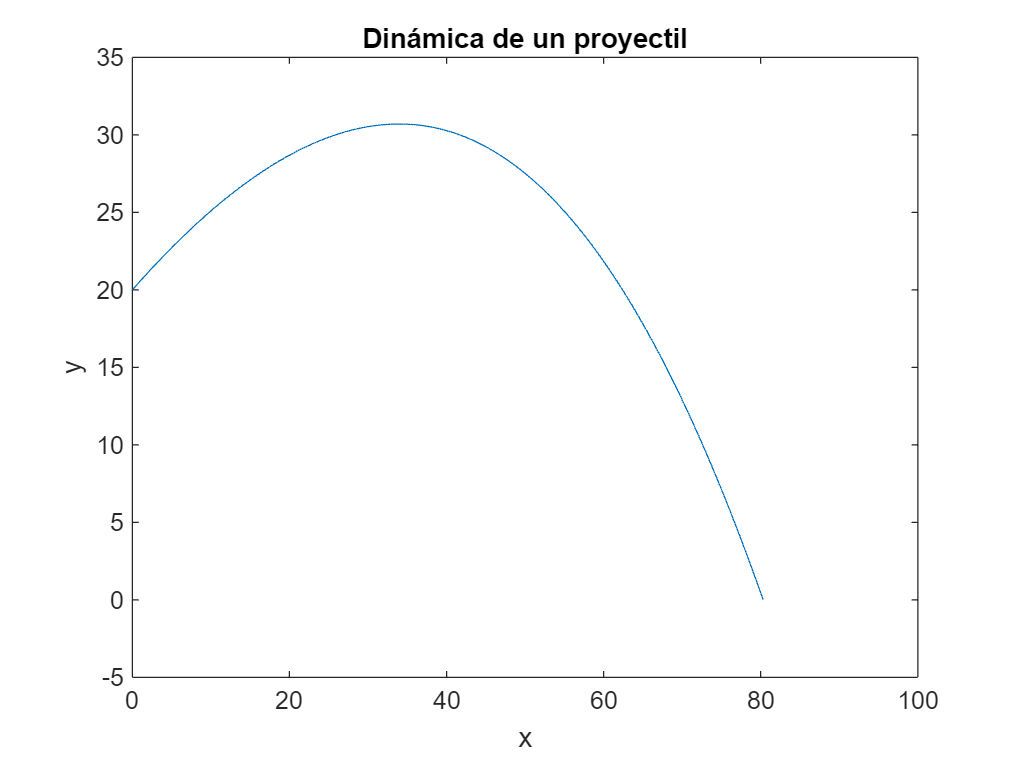

% Limpia las variables del workspace y cierra todas las figuras
clear all; close all

% Parámetros del modelo

rho=0.074;
Cd=0.87;
A=0.2;
velocidad_inicial=30;
angulo_inicial=pi/6;
g = 9.8;


% Condiciones iniciales
condiciones_iniciales = [0, velocidad_inicial*cos(angulo_inicial), 20, velocidad_inicial*sin(angulo_inicial)];

% Tiempo de integración
dt = 0.01;
intervalo_tiempo = 0:dt:10;

% Configura las opciones del solucionador de ODE con la función de evento
opciones = odeset('Events', @eventoCruceCero);

% Integra la ecuación con la condición de parada

[t, x] = ode45(@(t, x) proyectil(t, x, g, rho, A, Cd), intervalo_tiempo, condiciones_iniciales, opciones);

% Gráfica del resultado
figure;
plot(x(:,1), x(:,3));
xlabel('x');
ylabel('y');
title('Dinámica de un proyectil');

## Presentación de los Datos Empíricos

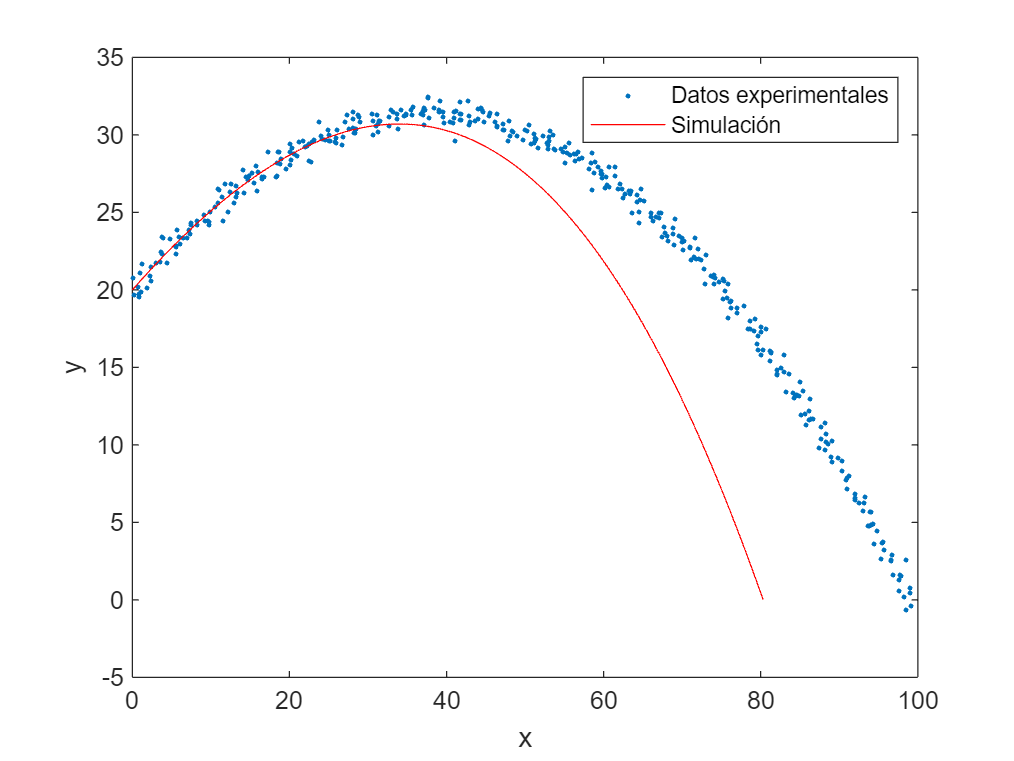

% Abrir los datos empíricos
load('EmpriricalData_noise.mat');
tiempo = datos_noise(:,1);
datos_experimentales = datos_noise(:,2:3);

% Grafica los datos experimentales con ruido
figure;
plot(datos_experimentales(:,1), datos_experimentales(:,2), '.');hold on
plot(x(:,1), x(:,3),'r');
xlabel('x');
ylabel('y');
legend('Datos experimentales','Simulación');

% Valor inicial para el coeficiente de arrastre
Cd_inicial = 0.87;

% Opciones para fminsearch
opciones_fmin = optimset('Display', 'iter', 'MaxIter', 100, 'TolX', 1e-8, 'TolFun', 1e-8);

% Ajusta Cd para minimizar el error
Cd_ajustado = fminsearch(@(Cd) ErrorFunction(Cd, datos_experimentales, tiempo, condiciones_iniciales), Cd_inicial, opciones_fmin)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          32544.8         
     1            2          32544.8         initial simplex
     2            4          26266.1         expand
     3            6            15019         expand
     4            8          975.796         expand
     5           10          975.796         contract outside
     6           12          216.057         contract inside
     7           14          216.057         contract inside
     8           16          216.057         contract inside
     9           18          216.057         contract outside
    10           20          216.057         contract inside
    11           22          216.057         contract inside
    12           24          216.057         contract inside
    13           26          216.027         contract inside
    14           28          216.027         contract inside
    15           30          216.026         contract inside
    16 

Cd_ajustado =    0.173450751185417


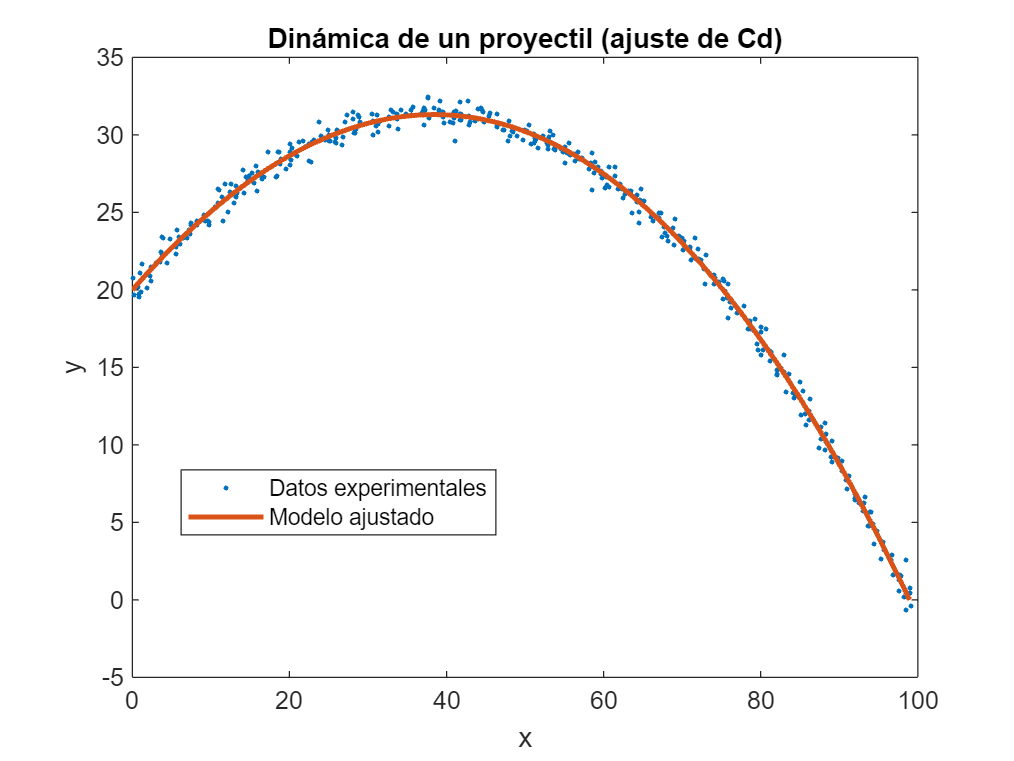


% Re-integra la ecuación con el valor de Cd ajustado
[t, x] = ode45(@(t, x) proyectil(t, x, g, rho, A, Cd_ajustado), intervalo_tiempo, condiciones_iniciales, opciones);

% Grafica el resultado comparando con los datos experimentales
figure;
plot(datos_experimentales(:,1), datos_experimentales(:,2), '.', x(:,1), x(:,3),'LineWidth',2);
xlabel('x');
ylabel('y');
title('Dinámica de un proyectil (ajuste de Cd)');
legend('Datos experimentales', 'Modelo ajustado');

legend("Position", [0.1836,0.29934,0.3,0.082143])

# Funciones Auxiliares

function dxdt = proyectil(t, x, g, rho, A, Cd)
    % Define the dynamics of the projectile
    % x(1): posición en x
    % x(2): velocidad en x
    % x(3): posición en y
    % x(4): velocidad en y
    dxdt = [x(2);...
           -sign(x(2)) * 0.5 * rho * A * Cd * x(2).^2;...
           x(4);...
           -g - sign(x(4)) * 0.5 * rho * A * Cd * x(4).^2];
end
%-----------------------------------------------------------------
function error = ErrorFunction(Cd, datos_experimentales,tspan, x0)

    % parámetros del modelo
    g = 9.8;
    rho=0.074;
    A=0.2;
    
    % Integrate the ODE with the candidate parameters
    [t, x] = ode45(@(t, x) proyectil(t, x, g, rho, A, Cd), tspan, x0);
    
    % Compute the error between model predictions and experimental data

    error = sum((x(:,1) - datos_experimentales(:,1)).^2 + ...
                (x(:,3) - datos_experimentales(:,2)).^2);    
    
end
%-----------------------------------------------------------------
function [value, isterminal, direction] = eventoCruceCero(t, x)
    % Set the value to be the variable x
    value = x(3);
    
    % Terminate the simulation when x crosses zero
    isterminal = 1;
    
    % Detect both increasing and decreasing zero crossings
    direction = 0;
end